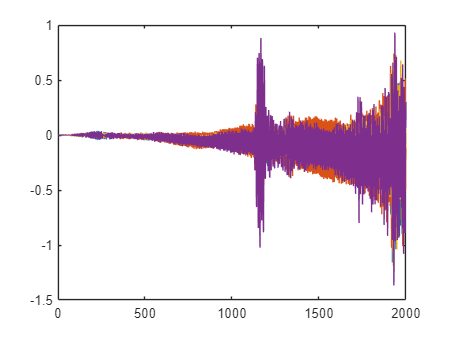

load test_data.mat -mat

%%test case%

sampleIndex = [1:1:2000;1:1:2000;1:1:2000;1:1:2000]';
sonarDistance = (sampleIndex/100000) * 1136;
timeGainValue = sonarDistance.^2.*(1/(4*pi)^2);


plot(time_gain_compensation(data, timeGainValue))

iterations = 10

iterations = 10

sum = 0;

for i=1:iterations
    tic
    time_gain_compensation(data, timeGainValue);
    time = toc;
    sum = sum+time;
end
averageRuntime = sum/iterations

averageRuntime = 4.1580e-05